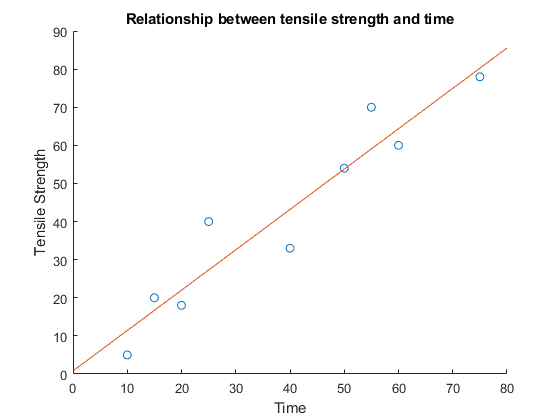

% MATLAB TEST 1 - 2019

% QUESTION 1

x = 0 : 5 : 30;
F = [0.0 9.0 13.0 14.0 10.5 12.0 5.0];
theta = [0.50 1.40 0.75 0.90 1.30 1.48 1.50];

% QUESTION 2

% initializing variables
time = [10 15 20 25 40 50 55 60 75];
strength = [5 20 18 40 33 54 70 60 78];
hold on
% plotting raw data
scatter(time, strength)

% renaming variables to make it more comfortable/intuitive to work with
x = time';
b = strength';
% creating matrix A
A = ones(length(x), 2);
A(:, 2) = x;
% let A* = A^T*A
A_star = A'*A;
% let b* = A^T*b
b_star = A'*b;
% coefficients to linear equation of best fit
coeffs = (inv(A_star) * b_star)';

% plotting best fit
t = [0 80];
y = (t .* coeffs(2)) + coeffs(1);
plot(t, y, '-')
xlabel('Time')
ylabel('Tensile Strength')
title('Relationship between tensile strength and time')